# Example: Dispersion Curves - PVDF Plate

Dispersion curves describe the modal solutions of the multilayer structure and describe a wave-mode which propagates parallel to layer-interfaces independently of a bulk wave. Exciting these modes is essential in ultrasonic inspection. Knowledge of the dispersion curves is useful for determining the most appropriate modes to excite and for optimizing the inspection process.

The implemented dispersion curve algorithm follows the procedure given in [1], however, this algorithm is not completely robust. It can be prone to missing the roots of dispersion curves and is sometimes unable to identify solutions for very leaky-guided modes. The ElasticMatrix software can calculate dispersion curves for simple layered structures (i.e., a plate in a vacuum or water). However, it is not robust for very-leaky cases, for example a plate embedded in an elastic medium. For these types of cases either Disperse [2], or other techniques based on the spectral-collocation method or semi-analytic finite element method are more appropriate. An example of the dispersion curves for a $1$\,mm titanium plate in a vacuum is shown in here. The dispersion curves are plotted on a graph of frequency vs wavenumber and show the first three symmetric $S$ and anti-symmetric $A$ Lamb modes. The results from Disperse are also plotted and have excellent agreement.

## Initialize ElasticMatrix Class

Initialize the ElasticMatrix class with a Medium object.

% A titanium plate:
plate_medium = Medium('vacuum',0,'PVDF',0.001,'vacuum',1);

% Initialize the model
model = ElasticMatrix(plate_medium);

## Setting Model Parameters

Set a range of frequencies to calculate the dispersion curves. The dispersion curves are calculated in terms of frequency-wavenumber, the range of wave-numbers is automatically calculated based on the lowest sound-speed within the medium. Only the first and last frequency are used.

% Set a range of frequencies:
model.setFrequency(linspace(0.1e6, 2.5e6, 2));

## Calculating Dispersion Curves

The dispersion curves are calculated using the .calculateDispersionCurve or .calculateDispersionCurveCoarse method. The .calculateDispersionCurve will attempt to trace the dispersion curves however, this does not always work correctly. If this is the case the .calculateDispersionCurveCoarse method can be used.

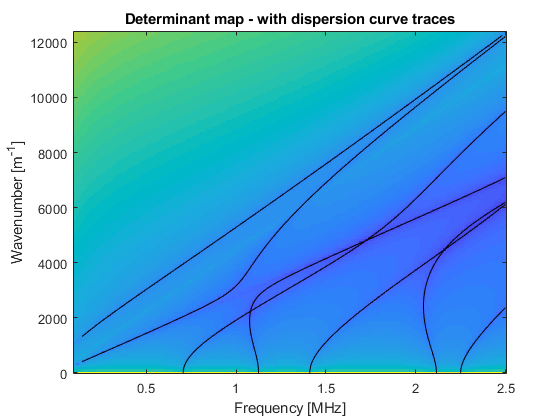

...calculating dispersion curves...


% Calculate the dispersion curves:
model.calculateDispersionCurves;

## Plotting Dispersion Curves

The dispersion curves can be plotted using the .plotDispersionCurves method. Note: the algorithm will occasionally identify the critical angle as a dispersion curve.

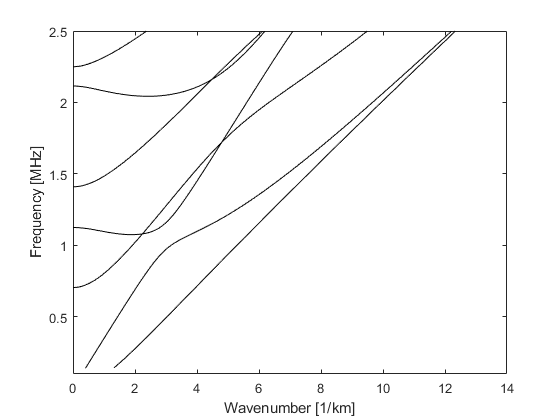

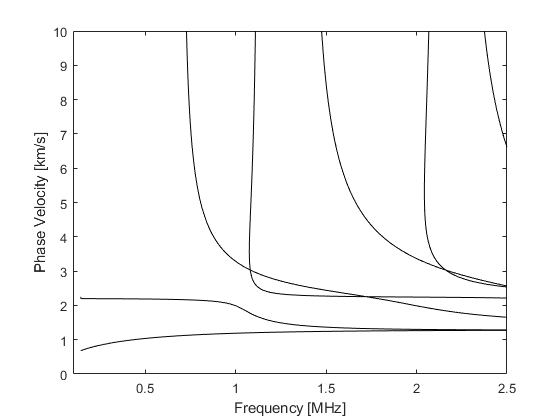

[figure_handles] = model.plotDispersionCurves;

## About

This file is part of the ElasticMatrix toolbox. Copyright (c) 2019 Danny Ramasawmy.

This file is part of ElasticMatrix. ElasticMatrix is free software: you can redistribute it and/or modify it under the terms of the GNU Lesser General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

ElasticMatrix is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU Lesser General Public License for more details.

You should have received a copy of the GNU Lesser General Public License along with ElasticMatrix. If not, see [http://www.gnu.org/licenses/](http://www.gnu.org/licenses/).